#  Local Basis Function Representations of Thermodynamic Surfaces 

# by J.Michael Brown

This script performs the calculations associated with the section titled: 

## Reanalysis of Sound Speed  Measurements for Water

The precise sound speed measurements of Lin and Trusler (2012) are revisited and compared with IAPWS-95.

Sections of this script construct figures given in the text. The outline of objectives for these figures is given below.

- Figure 1 shows the behavior of sound speeds as a function of pressure and temperature, the distribution of measurements and the location of the freezing line.

- In Figure 2, deviations of the Lin and Trusler sound speeds measurements from three surface representations are shown.  The first panel has deviations from IAPWS-95 derived sound speeds. The second panel gives measurement deviations from Lin and Trusler's polynomial fit. The third panel shows deviations from the local basis function (LBF) fit (constructed to fit measurements within reported uncertainties).

- In Figure 3, using the three representations, sound speeds are integrated (using function eqst) and the resulting densities and specific heats (derived from Gibbs energy LBF representations) are compared with those given by IAPWS-95.  The integration of IAPWS-95-derived sound speeds provides a test of the numerical methodology.

The major findings provided by this script are:

- A robust numerical framework utilizing local basis functions (LBF) is demonstrated that allows fits to measurements and analytic extraction of thermodynamic properties to arbitary precision.

- Extant sound speed data suggest that modifications to IAPWS-95 in a pressure regime of less than 400 MPa are warranted and the magnitude of required changes are articulated. 

##  SECTION ONE

 Construction of Figure 1

The figure in this section shows a sound speed surface, the distribution of measurements, and the location of the freezing line. At this scale variations between different surfaces fit to the measurements are indistingusihable

LT=LT_data;  % this loads the Lin and Trusler measurements into the workspace.
% create a grid of sound speeds based on IAPWS-95
P=0.1:10:434.1;
T=250:10:480;

A direct implementation of IAPWS is: 

 %results=IAPWS95({P,T},'P');

But here, a previously determine local basis function representation for IAPWS allows faster execution

results=fnIAPWSval({P,T}); 
vel=results.vel;

Here is an approximation for the melting phase lines from literature

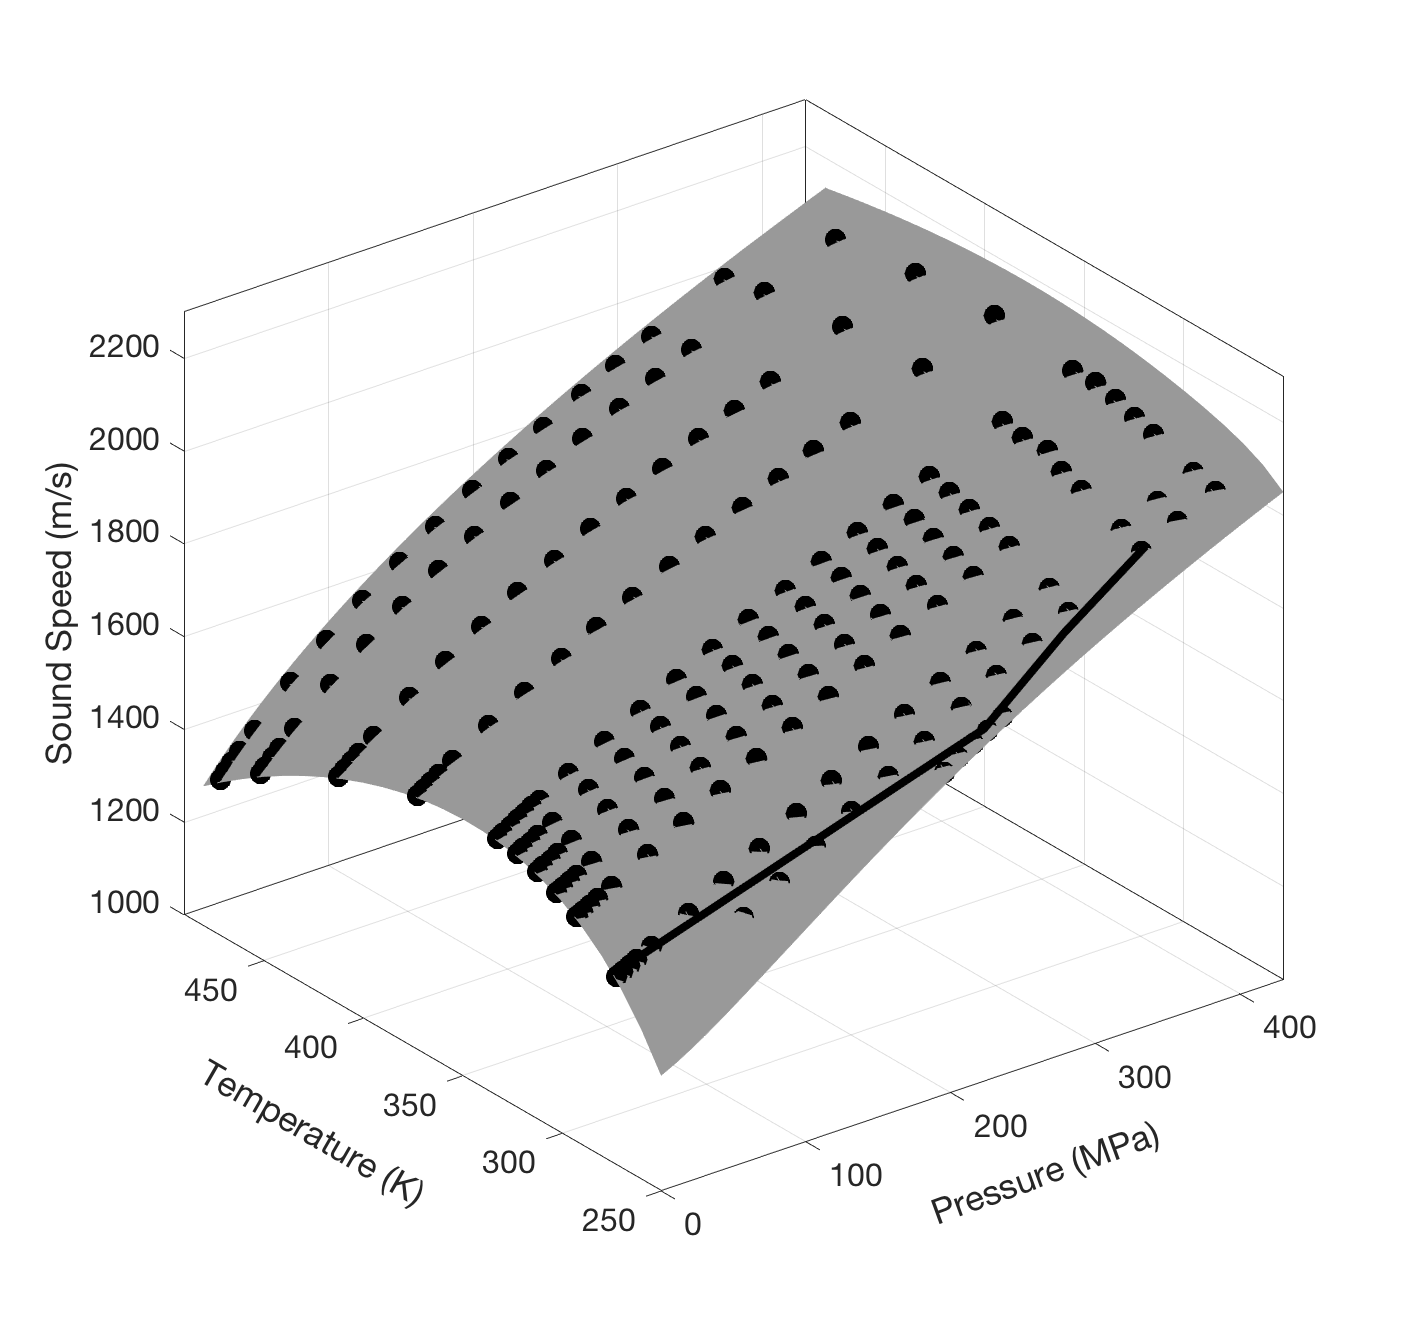

Tmelt=[273 252 257 261 266];
Pmelt=[0.1 226 mean([226 350]) 350 450];
nPm=length(Tmelt);
[Pm,Tm]=meshgrid(P,T);
Vmelt=interp2(Pm,Tm,1.01*vel',Pmelt,Tmelt);

% make Figure 1
figure1 = figure;
figure1.Name='Figure 1 Sound Speeds for Water';
figure1.NumberTitle='off';
figure1.Position=[111 136 709 669];
clf
% Create axes
axes1 = axes('Parent',figure1);
plot3(LT(:,1),LT(:,2),LT(:,3),'ko','MarkerFaceColor','k','MarkerSize',10)
hold on
plot3(Pmelt,Tmelt,Vmelt,'k-','LineWidth',4)
surf(P,T,vel','SpecularExponent',1,...
    'FaceColor',[.6 .6 .6],...
     'EdgeColor',[.6 .6 .6]) 
hold off
box 'on'
axis([ 0 430 250 490 1000 2300])
xlabel('Pressure (MPa)','FontSize',20,'rotation',20)
ylabel('Temperature (K)','FontSize',20,'rotation',-30)
zlabel('Sound Speed (m/s)','FontSize',20)
set(axes1,'FontSize',16);
grid on
hold off

Sound speeds and melting phase boundaries for water. The surface gives predictions using IAPWS-95. The black circles are measurements given by Lin and Trusler. The lines show melting bourdaries as a function of pressure.

SECTION TWO

For Figure 2, deviations of the Lin and Trusler sound speeds measurements from three surface representations are plotted.  The first panel shows measurement deviations from IAPWS-95 derived sound speeds. The second panel shows measurement deviations from Lin and Trusler's polynomial fit to the sound speed measurements. The third panel shows measurement deviations from the LBF fit (constructed to fit measurements within reported uncertainties). A key finding is that measurements deviate systematically both from IAPWS-95 and from the polynomial representation of the measurements.

% set up parameters for spline fit toLT data
clear options
Pc=linspace(0,500,50);   % control points in pressure for sound speed fit
Tc=linspace(240,500,50); % control points in temperature for sound speed fit
options.Xc={Pc,Tc};
options.lam=[70 60];  % lam chosen to achieve chi sqr ~ 1
% do fit:
sp_LTFit=spdft(LT(:,1:2),LT(:,3),LT(:,4),options);  % call to spline fitting function
sp_LTFit.Data  % if uncommented this displays the statistics of fit in command window

ans = struct with fields:
          X: [212×2 double]
          Y: [212×1 double]
         Yc: [212×1 double]
    Ycontrl: [50×50 double]
     Uncert: [212×1 double]
         Xc: {[1×50 double]  [1×50 double]}
        lam: [70 60]
       mdrv: [2 2]
     RegFac: [1 1]
        rms: 0.32397
       devs: [212×1 double]
     chisqr: 0.99769



% This evaluates IAPWS at Lin and Trusler data sites
resultsd=fnIAPWSval(LT(:,1:2));
veld=resultsd.vel;
%This returns sound speeds at data sites per the polynomial reported in Lin and Trusler 
velLTFd=returnLTv(LT(:,1:2));

% This returns sound speeds per the local basis function fit
velLTMFd=fnval(sp_LTFit,LT(:,1:2)');

% calculate percentage deviations of the Lin and Trusler sound speeds from
% the three representations
devsLTi=1e2*((LT(:,3)-veld)./(LT(:,3)));
devsLTF=1e2*((LT(:,3)-velLTFd)./(LT(:,3)));
devsLTMF=1e2*((LT(:,3)-velLTMFd')./(LT(:,3)));

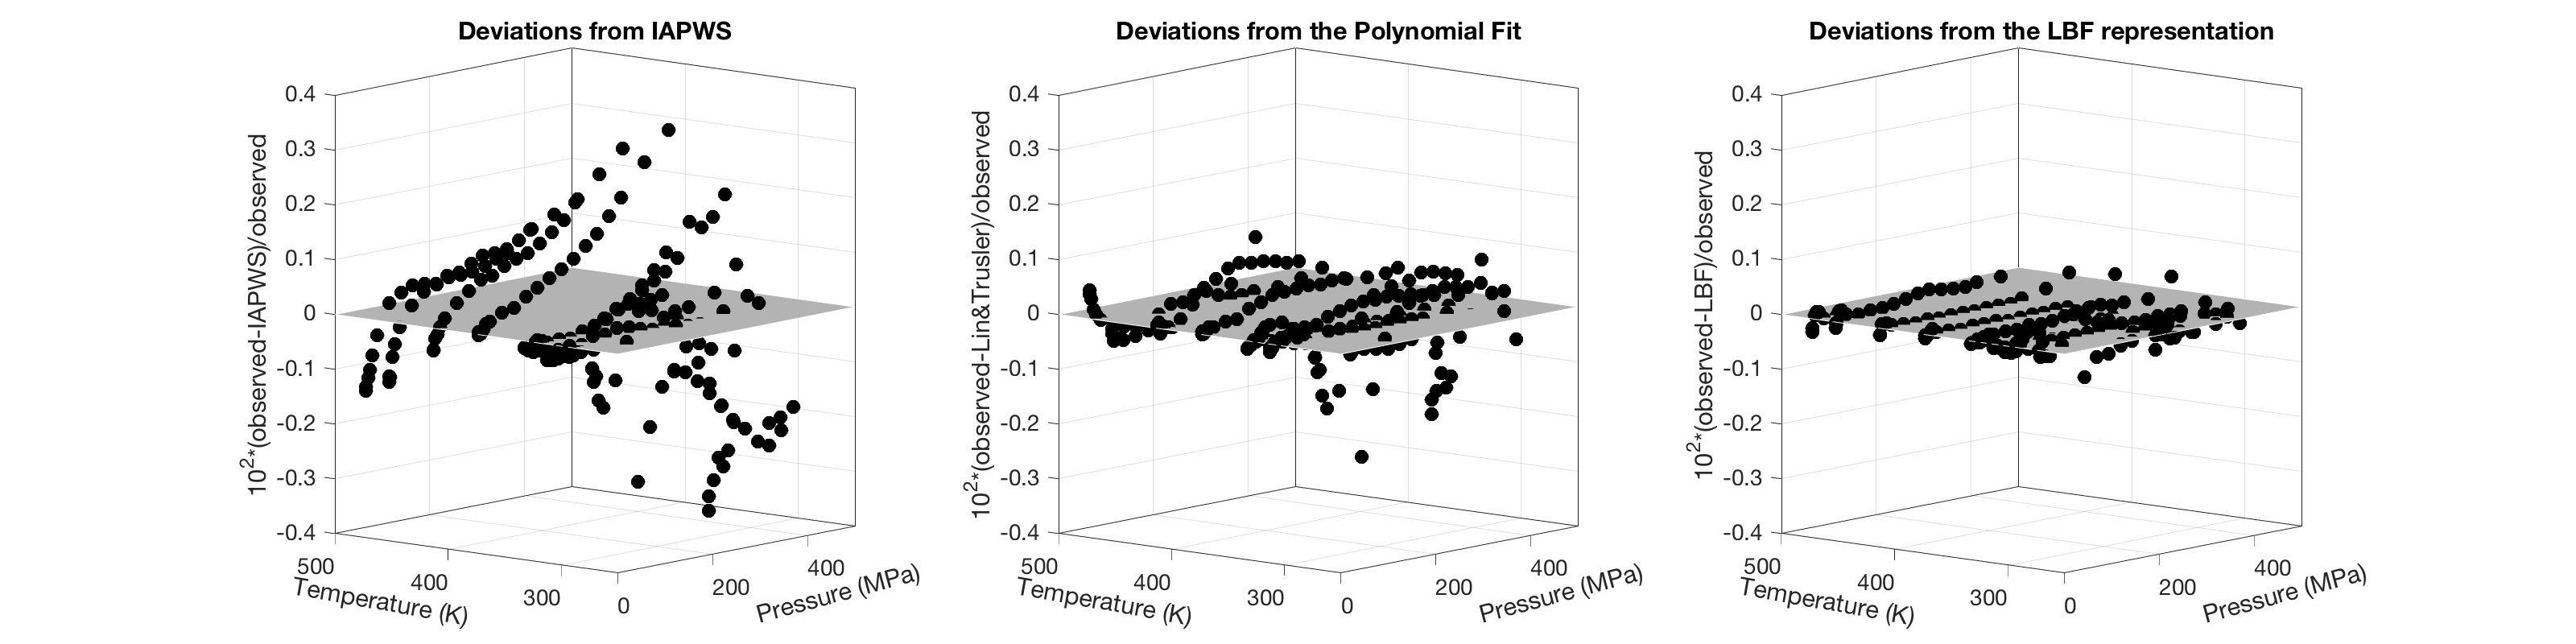


% make the plots
figure2=figure;
figure2.Name='Figure 2 Sound Speed Deviations';
figure2.NumberTitle='off';
figure2.Position=[100 100 1600 400];
sp1=subplot(131);
plot3(LT(:,1),LT(:,2),devsLTi,'ko','MarkerFaceColor','k','MarkerSize',8)
hold on
surf([0 0 500 500 0],[250 500 500 250 250],zeros(5,5),'FaceColor',[0.7 0.7 0.7],...
    'EdgeColor',[1 1 1],...
    'AlphaData',0.3)
ylabel('Temperature (K)','FontSize',20,'Rotation',-10)
xlabel('Pressure (MPa)','FontSize',20,'Rotation',15)
zlabel('10^2*(observed-IAPWS)/observed','FontSize',20)
axis([0 500 250 500 -.4 .4])
view([-50 8])
set(sp1,'FontSize',14);
hold off
title('Deviations from IAPWS')
grid on
box on

sp2=subplot(132);
plot3(LT(:,1),LT(:,2),devsLTF,'ko','MarkerFaceColor','k','MarkerSize',8)
hold on
surf([0 0 500 500 0],[250 500 500 250 250],zeros(5,5),'FaceColor',[0.7 0.7 0.7],...
    'EdgeColor',[1 1 1],...
    'AlphaData',0.3)
axis([0 500 250 500 -.4 .4])
ylabel('Temperature (K)','FontSize',20,'Rotation',-10)
xlabel('Pressure (MPa)','FontSize',20,'Rotation',15)
view([-50 8])
zlabel('10^2*(observed-Lin&Trusler)/observed','FontSize',20)
set(sp2,'FontSize',14);
hold off
title('Deviations from the Polynomial Fit')
box on
grid on

sp3=subplot(133);
plot3(LT(:,1),LT(:,2),devsLTMF,'ko','MarkerFaceColor','k','MarkerSize',8)
hold on
surf([0 0 500 500 0],[250 500 500 250 250],zeros(5,5),'FaceColor',[0.7 0.7 0.7],...
    'EdgeColor',[1 1 1],...
    'AlphaData',0.3)
axis([0 500 250 500 -.4 .4])
ylabel('Temperature (K)','FontSize',30,'Rotation',-10)
xlabel('Pressure (MPa)','FontSize',30,'Rotation',15)
view([-50 8])
zlabel('10^2*(observed-LBF)/observed','FontSize',30)
set(sp3,'FontSize',14);
title('Deviations from the LBF representation')
hold off
box on
grid on

Deviations as a function of pressure and temperature of sound speeds measurements for water from three representations. A constant vertical scale of +/-0.4% is used.  Left panel shows deviations from IAPWS-95.  Systematic behavior that is much larger (+/-0.3%) than experimental uncertainty suggests a need to correct IAPWS-95. The middle panel shows deviations of measurements from the polynomial fit reported by Lin and Trusler.  Here the remaining systematic deviations (particularly at low temperature) suggest that the custom representation is not adequately fitting data within stated experimental uncertainty. The right-side panel shows deviations of measurements from the LBF representation.  A fit within experimental uncertainty was required in construction of the LBF representation.

SECTION THREE 

Using three representations for sound speeds (IAPWS-95, the Lin and Trusler fit, and a LBF representation), equations of state are calculated and the resulting densities and specific heats are compared with those given by IAPWS-95.  Using IAPWS-95 sound speeds as an input to the calcuations is a test of the methodology.

The function "eqst" uses a "predictor-corrector" algorithm to solve the following coupled equation for specific volume ($V=1/\rho$) where $\rho$ is density, $C_p$ is specific heat, *c* is sound speed, and $\alpha$ is thermal expansivity:

  $\frac{d\left(1/V\right)}{\mathrm{dP}}=\frac{1}{c^2 }+\frac{\alpha^2 T}{C_P }$   where $\alpha =\frac{1}{V}\frac{\mathrm{dV}}{\mathrm{dT}}$ and $\frac{dC_P }{\text{dP}}=-T\frac{d^2 V}{dT^2 }$

The "correction" term, $\frac{\alpha^2 T}{C_P }$, is the adiabatic to isothermal correction.  It's evaluation requires a fit of volumes vs T at each pressure step. Specific heat and density must be specified at the starting (reference) pressure. A trial value for the correction term is calculated and density (specific volume) is estimated at the next pressure step by trapezoidal integration. The trial specific volumes are fit with a 6th order spline and first and second derivatives provide updated estimates for thermal expansion and specific heat at the higher pressure point. An updated correction term is used to redetermine the integrated densities. For each pressure step, the calculation of the new density is repeated until the correction term converges.  

The evaluation of the correction term can result in instabilities that grow with pressure.  These are controlled in two ways.  Regularization is used in the determination of a spline through the volume vs T points.  The 4th derivative of V is required to be small (insuring that the pressure derivative of Cp vs T is smooth). A second level of regularization is implemented as a low-pass filter on Cp vs T.   These two constraints are separately controlled as documented in the setup of the "options" structure.

Note that other regularization (that thermal expansivity is "smooth" ) could be implemented as a non-linear constraint. This would slow the integration substantially. The current implementation using the low-pass filtering has proven adequate.

Make Figure 3a 

Construct a data grid for problem

Pd=0.1:2:400.1; %  points in P that are used for integration as a function of pressure 
%                  (defined in MPa)

Here the temperature grid is logrithmic - allowing more points at low T where the temperature  dependence is larger

Td=logspace(log10(252),log10(474),400); 
Td(1)=252; Td(end)=474; % the logspace function returns end points that may deviate by
%                           machine precision from those specified - this forces
%                            them to match at the edge
PTd={Pd',Td'};

results=fnIAPWSval(PTd);  % this is the local basis function representation of IAPWS
rhoi=results.rho;
veli=results.vel;
Gi=results.G;
Cpi=results.Cp;
mask=results.mask;  % this provides NaN's for grid points in the metastable regime

Here the Lin and Trusler polynomial is evaluated on the specified grid  - since it is a slow evaluation,  a section break is supplied so that one does not need to recalculate these points if later sections are modified

tic
velLTF=returnLTv(PTd);
toc

Elapsed time is 45.920503 seconds.


The input structures for eqst are "Data" and "options".  Here options parameter are set that control calculations using eqst

clear options_eqst  % insure that there is not a previous version in the workspace
options_eqst.nTc=100;  % number of control points to be used
options_eqst.loglam_start=-1; % log of damping parameter at 1 bar
options_eqst.loglam_end=-1;   % log of damping parameter at the highest pressure
options_eqst.Cpsmoothflg=1;  % if set to 1, this low-pass filters the temperature variation 
%                               of volume at each pressure step of integration
options_eqst.lp=.29;  % the low-pass cut-off as a fraction of the sampling frequency 


Set input data struction for calculation (define all values on a grid)

Data.PT=PTd;  % the grid of pressures and temperatures for the calculations
Data.vel=veli; % sound speeds at all pressure and temperatures here set to IAPWS values
Data.rhoin=rhoi(1,:);  % densities at the starting pressure for all T (from IAPWS-95)
Data.Cpin=Cpi(1,:); % Specific Heats at the starting pressure for all T (from IAPWS-95)
Data.Go=Gi(1,:);   % Gibbs energies at the starting pressure for all T (from IAPWS-95)

Here is the sound speed integration

eqst_out=eqst(Data,options_eqst);

Save the resulting densities, Gibbs energies, and Cp's to local variables

rhoiI=eqst_out.rho;
CpiI=eqst_out.Cp;
GiI=eqst_out.G;


Now convert G, rho, and Cp from eqst into a single LBF representation

Start by setting options for the fitter

clear optionsG

Set the control points for the local basis functions - first example is "overkill"

optionsG.PTmc={linspace(0,400.1,200),logspace(log10(250),log10(475),200)};

Here the size of the spline is reduced by cutting back on the control point density by using a denser spacing in T at low T and wide spacing at higher T.  Other options are allowed to be the default values

optionsG.PTmc={linspace(0,400.1,20),[250:2.5:279 linspace(280,480,40)]};
optionsG.normflg=1; 
optionsG.weight=[1e3 1e2];

Find the LBF representation for Gibbs Energy:

sp_GiI=spgft(PTd,GiI(:,:),rhoiI,CpiI,optionsG); 

Evaluate properties of the new representation on the grid 

out_G=fnGval(sp_GiI,PTd);  
rhociI=out_G.rho;
velciI=out_G.vel;
GciI=out_G.G;
CpciI=out_G.Cp;

Plot deviations of representation to IAPWS:

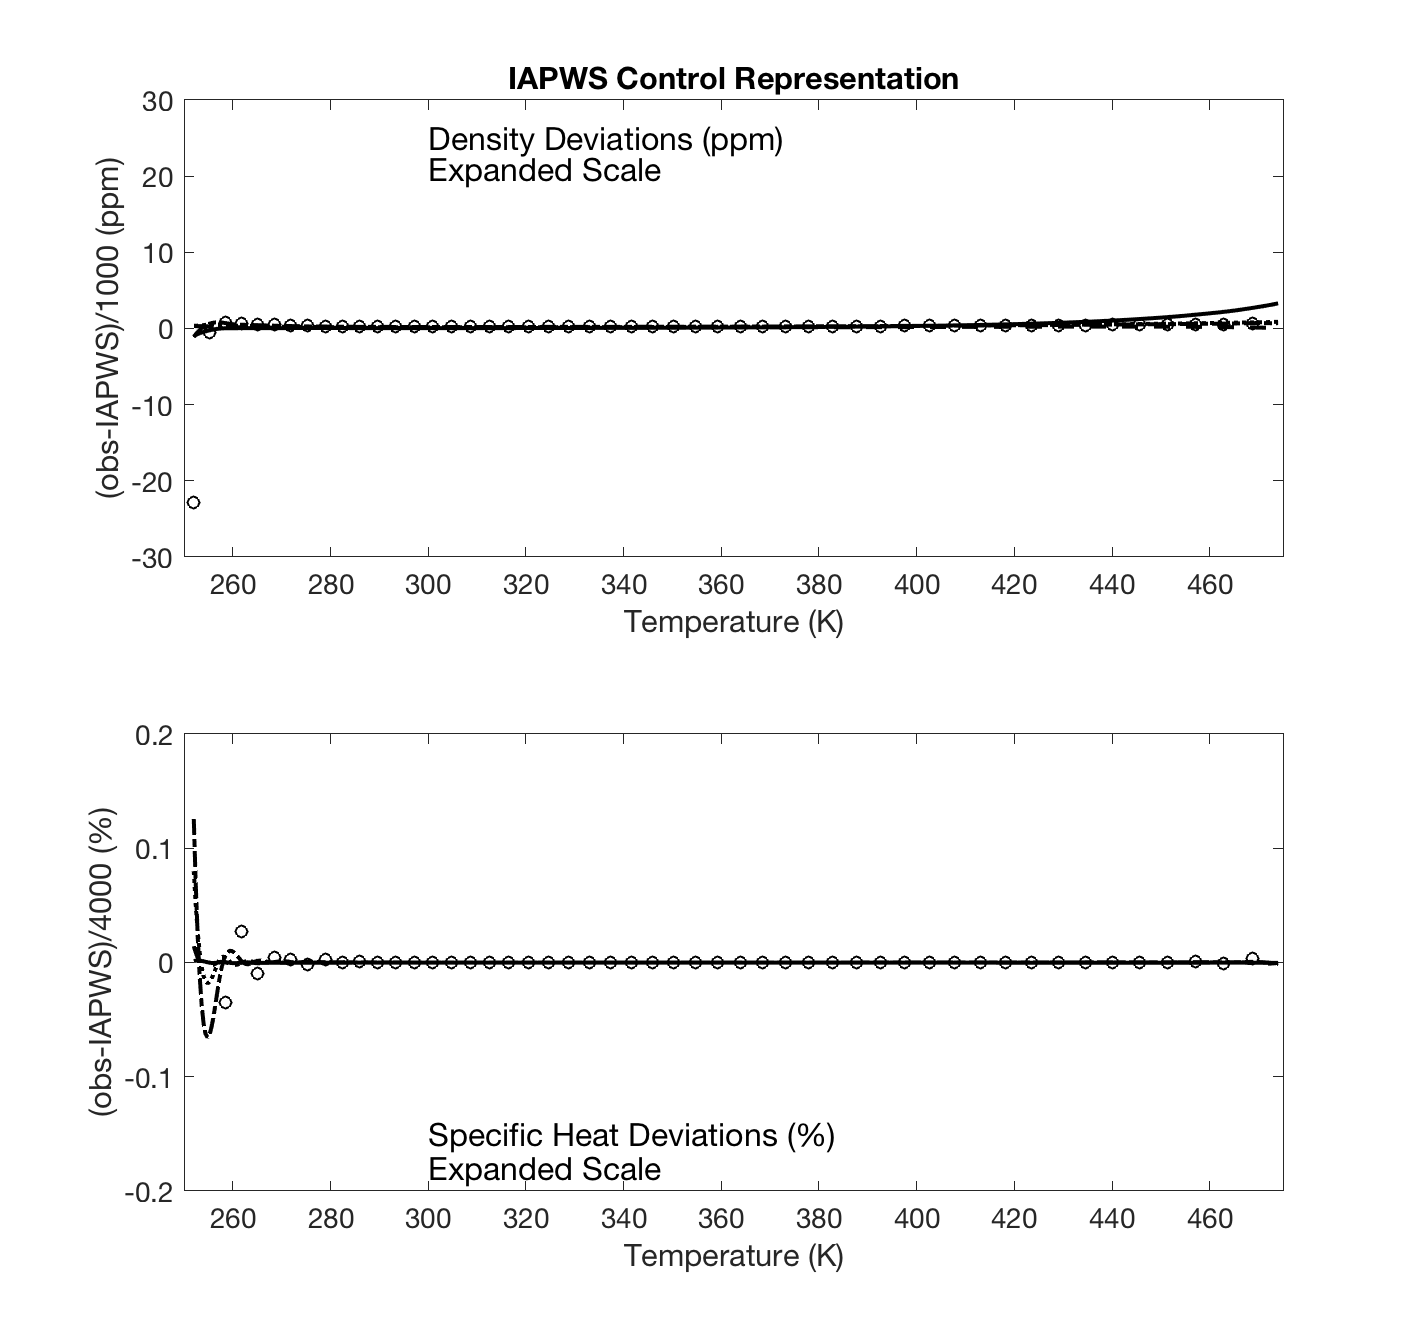

figure3 = figure;
figure3.Name='Figure 3 Equations of State Deviations';
figure3.NumberTitle='off';
figure3.Position=[111 136 709 669];
clf
% Create axes
axes3 = axes('Parent',figure3);
txt1='Density Deviations (ppm)';
txt2='Specific Heat Deviations (%)';
txt3='Expanded Scale';
np=length(Pd);
pid=[1 51 101 151 201]; % plot .1 100 200 300 and 400 MPa results

subplot1=subplot(211);
plot(Td,1e6*(rhociI(pid(1),:)-rhoi(pid(1),:))/1000,'k-','LineWidth',2)
hold on
plot(Td,1e6*(rhociI(pid(2),:)-rhoi(pid(2),:))/1000,'k--','LineWidth',2)
plot(Td,1e6*(rhociI(pid(3),:)-rhoi(pid(3),:))/1000,'k:','LineWidth',2)
plot(Td,1e6*(rhociI(pid(4),:)-rhoi(pid(4),:))/1000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e6*(rhociI(pid(5),1:8:end)-rhoi(pid(5),1:8:end))/1000,'ko')
hold off
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/1000 (ppm)','FontSize',20)
title('IAPWS Control Representation','FontSize',20)
axis([250 475 -30 30])
set(subplot1,'FontSize',14);
text(300,25,txt1,'FontSize',16)
text(300,21,txt3,'FontSize',16)

subplot2=subplot(212);
plot(Td,1e2*(CpciI(pid(1),:)-Cpi(pid(1),:))/4000,'k-','LineWidth',2)
hold on
plot(Td,1e2*(CpciI(pid(2),:)-Cpi(pid(2),:))/4000,'k--','LineWidth',2)
plot(Td,1e2*(CpciI(pid(3),:)-Cpi(pid(3),:))/4000,'k:','LineWidth',2)
plot(Td,1e2*(CpciI(pid(4),:)-Cpi(pid(4),:))/4000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e2*(CpciI(pid(5),1:8:end)-Cpi(pid(5),1:8:end))/4000,'ko')
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/4000 (%)','FontSize',20)
axis([250 475 -.2 .2])
set(subplot2,'FontSize',14);
text(300,-.15,txt2,'FontSize',16)
text(300,-.18,txt3,'FontSize',16)
hold off

Deviations from IAPWS-95 of densities and specific heats determined by integrating sound speeds for water based on IAPWS-95. Four isobars vs temperature are shown: 1 bar (solid), 100 MPa (long dash), 200 MPa (short dash), 300 MPa (short-long dash), and 400 MPa (open circles). This comparison to a reference model is undertaken to establish that the numerical framework is accurate.  Here densities are recovered to parts-per-million and specific heats are recovered to a few hundreths of percent. These errors can be made arbitrarily smaller through adjustment of control points, input data, and choices for regularization.

 Make Figure 3b by Integrating the Lin and Trusler polynomial for sound speeds. Here the results should agree with those previously published.

Set sound speeds to the values from the Lin and Trusler representation:

Data.vel=velLTF;

Integrate the sound speeds (using options that previously worked for the IAPWS-95 analysis). Don't bother fitting to Gibbs energy - would give the same plots.

eqst_out=eqst(Data,options_eqst);
rhocLT=eqst_out.rho;
CpcLT=eqst_out.Cp;
GcLT=eqst_out.G;

Plot deviations relative to IAPWS

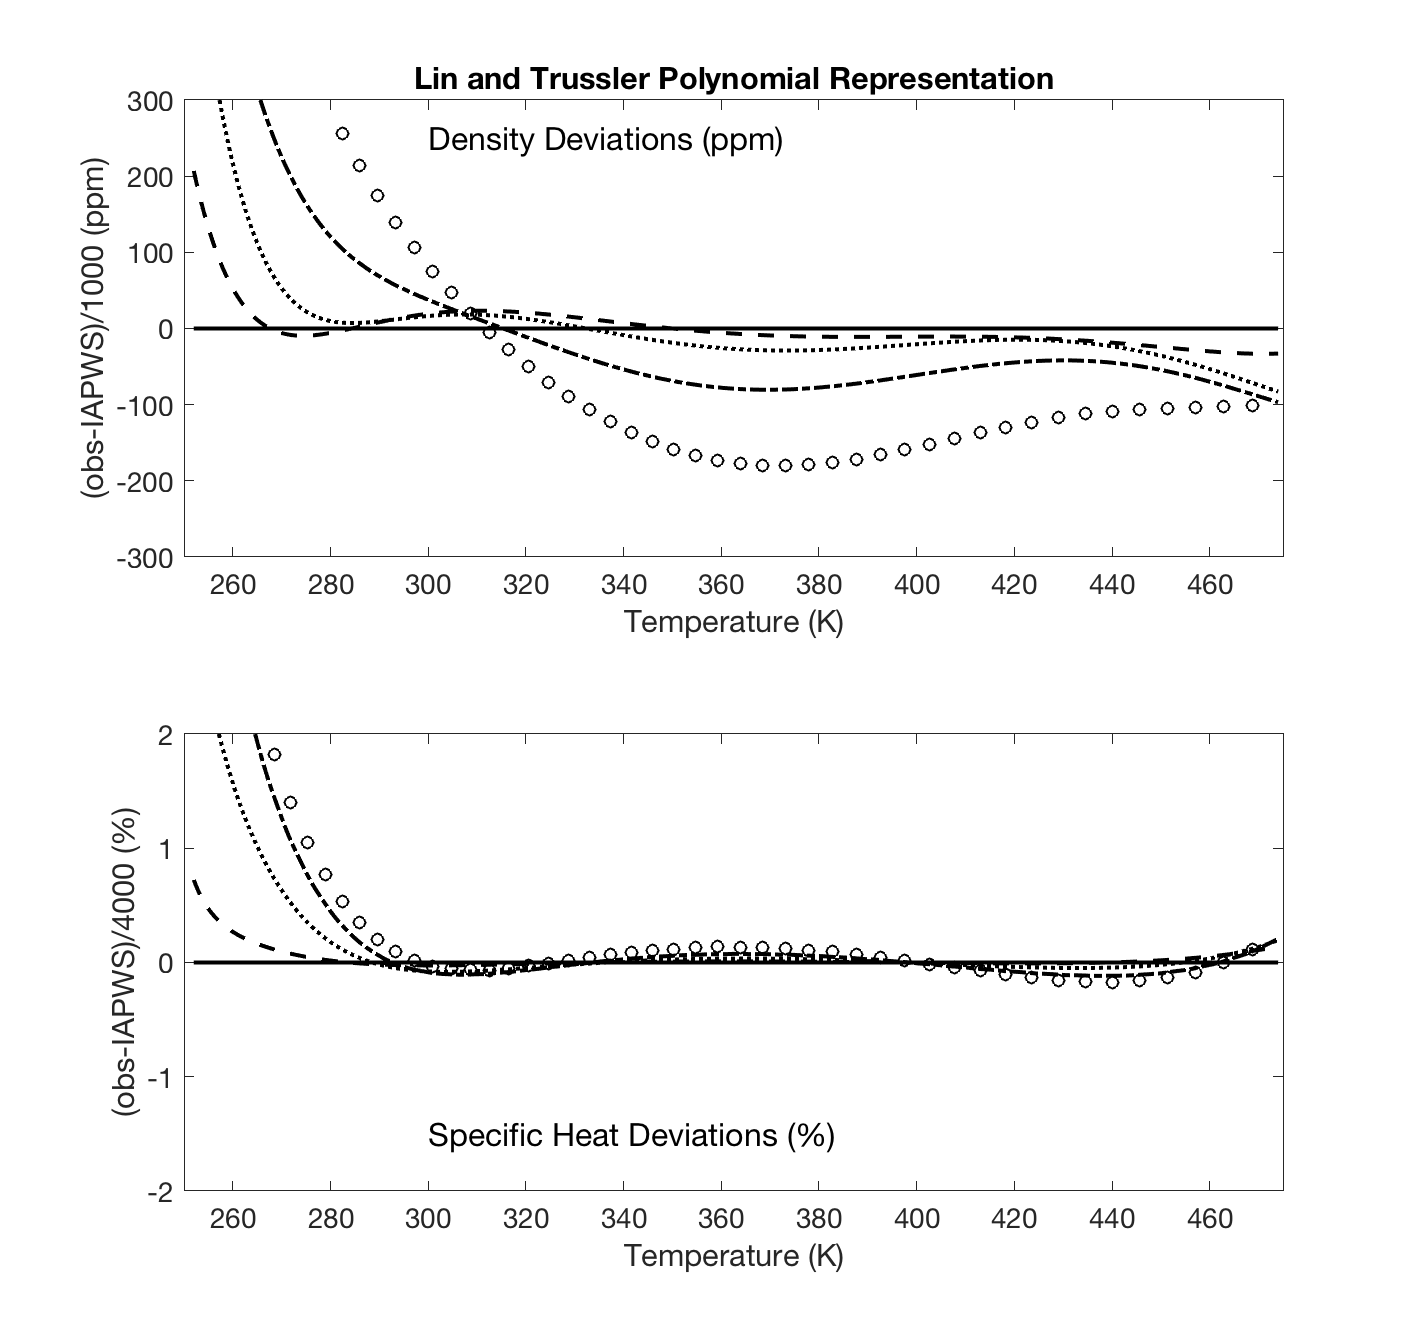

subplot3=subplot(211);
plot(Td,1e6*(rhocLT(pid(1),:)-rhoi(pid(1),:))/1000,'k-','LineWidth',2)
hold on
plot(Td,1e6*(rhocLT(pid(2),:)-rhoi(pid(2),:))/1000,'k--','LineWidth',2)
plot(Td,1e6*(rhocLT(pid(3),:)-rhoi(pid(3),:))/1000,'k:','LineWidth',2)
plot(Td,1e6*(rhocLT(pid(4),:)-rhoi(pid(4),:))/1000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e6*(rhocLT(pid(5),1:8:end)-rhoi(pid(5),1:8:end))/1000,'ko')
hold off
title('Lin and Trussler Polynomial Representation','FontSize',20)
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/1000 (ppm)','FontSize',20)
axis([250 475 -300 300])
set(subplot3,'FontSize',14);
text(300,250,txt1,'FontSize',16)

subplot4=subplot(212);
plot(Td,1e2*(CpcLT(pid(1),:)-Cpi(pid(1),:))/4000,'k-','LineWidth',2)
hold on
plot(Td,1e2*(CpcLT(pid(2),:)-Cpi(pid(2),:))/4000,'k--','LineWidth',2)
plot(Td,1e2*(CpcLT(pid(3),:)-Cpi(pid(3),:))/4000,'k:','LineWidth',2)
plot(Td,1e2*(CpcLT(pid(4),:)-Cpi(pid(4),:))/4000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e2*(CpcLT(pid(5),1:8:end)-Cpi(pid(5),1:8:end))/4000,'ko')
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/4000 (%)','FontSize',20)
axis([250 475 -2 2])
set(subplot4,'FontSize',14);
text(300,-1.5,txt2,'FontSize',16)
hold off

Deviations from IAPWS-95 of densities and specific heats determined by integration of the Lin and Trusler polynomial representation for sound speeds of water.  Four isobars vs temperature are shown: 1 bar (solid), 100 MPa (long dash), 200 MPa (short dash), 300 MPa (short-long dash), and 400 MPa (open circles). The ranges of deviations +/- 300 ppm for densities and +/-2% for specific heats and the behavior plotted are consistent with previously published results.

Make Figure 3c by integrating the LBF representation for sound speeds and then solving for a LBF Gibbs energy representation.   This provides two major improvements over the previously reported results:

- The sound speed representation is more consistent with measurements - significant systematic deviations visible in the polynomial representation are removed.

- The final product is a single LBF representation for Gibbs energy that can be appropriately differentiated (analytically) to predict thermodynamic properties.  In earlier work, only tables of densities and specific heats or separately fit functional descriptions were provided.

Get sound speeds from the LBF representation evaluated on the grid for the integration

Data.vel=fnval(sp_LTFit,PTd);

Integrate sound speeds

eqst_out=eqst(Data,options_eqst); %Integrate sound speeds to get density and Cp
rhoLTM=eqst_out.rho;
CpLTM=eqst_out.Cp;
GLTM=eqst_out.G;

Determine the representation of Gibbs energy

sp_GLTM=spgft(PTd,GLTM(1,:),rhoLTM,CpLTM,optionsG);

Evaluate properties from this Gibbs representation

out_LTM=fnGval(sp_GLTM,PTd); 
rhocLTM=out_LTM.rho;
velLTM=out_LTM.vel;
GcLTM=out_LTM.G;
CpcLTM=out_LTM.Cp;

Plot deviations from IAPWS-95:

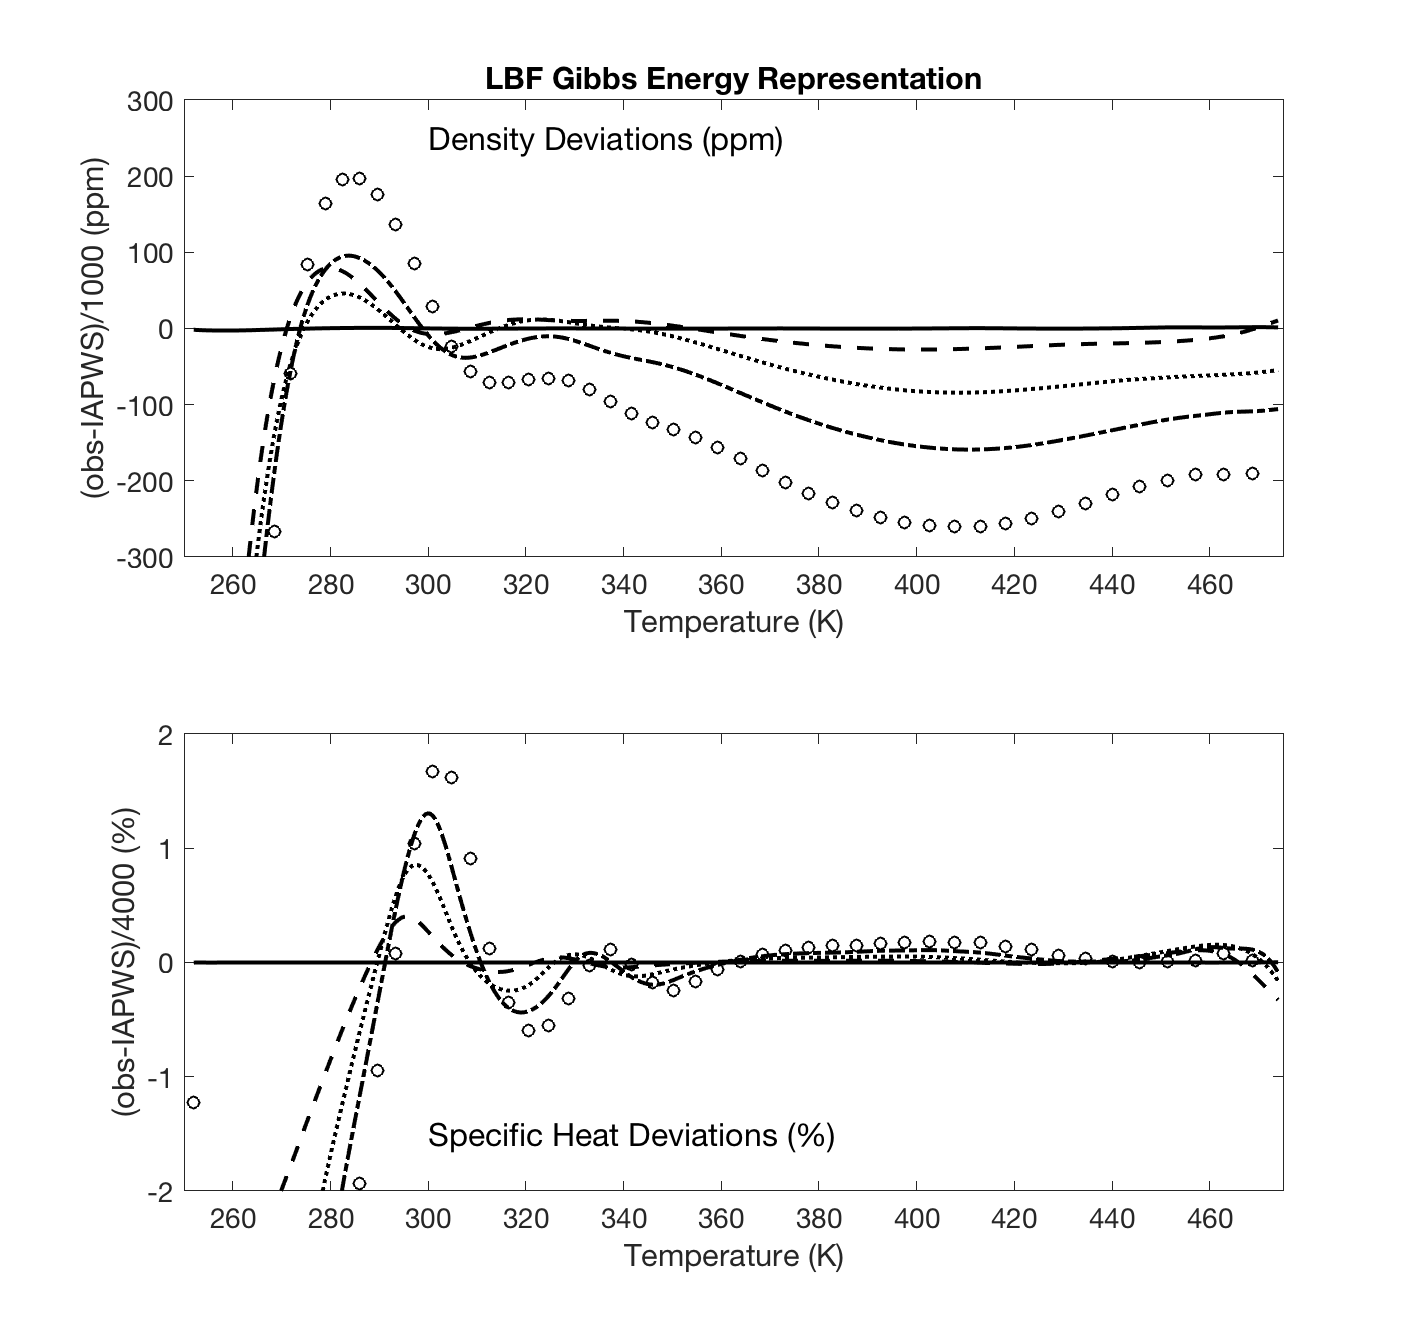

subplot5=subplot(211);
plot(Td,1e6*(rhocLTM(pid(1),:)-rhoi(pid(1),:))/1000,'k-','LineWidth',2)
hold on
plot(Td,1e6*(rhocLTM(pid(2),:)-rhoi(pid(2),:))/1000,'k--','LineWidth',2)
plot(Td,1e6*(rhocLTM(pid(3),:)-rhoi(pid(3),:))/1000,'k:','LineWidth',2)
plot(Td,1e6*(rhocLTM(pid(4),:)-rhoi(pid(4),:))/1000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e6*(rhocLTM(pid(5),1:8:end)-rhoi(pid(5),1:8:end))/1000,'ko')
hold off
title('LBF Gibbs Energy Representation','FontSize',20)
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/1000 (ppm)','FontSize',20)
axis([250 475 -300 300])
set(subplot5,'FontSize',14);
text(300,250,txt1,'FontSize',16)

subplot6=subplot(212);
plot(Td,1e2*(CpcLTM(pid(1),:)-Cpi(pid(1),:))/4000,'k-','LineWidth',2)
hold on
plot(Td,1e2*(CpcLTM(pid(2),:)-Cpi(pid(2),:))/4000,'k--','LineWidth',2)
plot(Td,1e2*(CpcLTM(pid(3),:)-Cpi(pid(3),:))/4000,'k:','LineWidth',2)
plot(Td,1e2*(CpcLTM(pid(4),:)-Cpi(pid(4),:))/4000,'k-.','LineWidth',2)
plot(Td(1:8:end),1e2*(CpcLTM(pid(5),1:8:end)-Cpi(pid(5),1:8:end))/4000,'ko')
xlabel('Temperature (K)','FontSize',20)
ylabel('(obs-IAPWS)/4000 (%)','FontSize',20)
axis([250 475 -2 2])
set(subplot6,'FontSize',14);
text(300,-1.5,txt2,'FontSize',16)
hold off

Deviations from IAPWS-95 of densities and specific heats based on the LBF representation of Gibbs energy obtained through integration of the LBF sound speed representation of the Lin and Trusler data.  Four isobars vs temperature are shown: 1 bar (solid), 100 MPa (long dash), 200 MPa (short dash), 300 MPa (short-long dash), and 400 MPa (open circles). Most trends shown here are similar to those given in the Lin and Trusler evaluation of their data.  Densities above room temperature show negative deviations relative to IAPWS-95 and specific heats are not significantly different.  However, in regimes where the Lin and Trusler polynomial fit shows systematic difference from data (particularly at low temperatures), the inferred equation of state is different.  Here density and Cp deviations trend more strongly negative at low T. 